# MATLAB Assignment 3- Slice an Image

## Select the Image

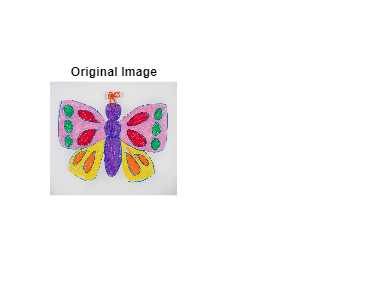

% Let the user choose an image file
[filename, pathname] = uigetfile({'*.jpg;*.png;*.bmp', 'Image Files (*.jpg, *.png, *.bmp)'}, 'Select an Image');
if isequal(filename,0) || isequal(pathname,0)
    disp('User canceled the operation. Exiting...');
    return;
end

% Read the selected image
originalImage = imread(fullfile(pathname, filename));

% Display the original image
subplot(1,2,1), imshow(originalImage), title('Original Image');

## Decide the Parameters

% Ask the user how they want to split the image
splitMethod = questdlg('How do you want to split the image?', ...
                       'Split Image', ...
                       'Equal Parts', 'Specify Number of Parts', 'Cancel', 'Equal Parts');
if strcmp(splitMethod, 'Cancel')
    disp('User canceled the operation. Exiting...');
    return;
end

if strcmp(splitMethod, 'Equal Parts')
    % Ask the user for the number of equal parts
    numParts = inputdlg('Enter the number of equal parts:');
    if isempty(numParts)
        disp('User canceled the operation. Exiting...');
        return;
    end
    numParts = str2double(numParts{1});
    
    if isnan(numParts) || numParts <= 1
        disp('Invalid input. Number of parts must be a positive integer greater than 1.');
        return;
    end
    
    % Determine the size of the image
    [rows, columns, ~] = size(originalImage);
    
    if numParts > rows && numParts > columns
        disp('Invalid input. Number of parts exceeds the size of the image.');
        return;
    end
    
    % Split the image into equal parts
    if rows >= columns
        splitPoints = round(linspace(0, rows, numParts+1));
        firstPart = cell(1, numParts);
        for i = 1:numParts
            firstPart{i} = originalImage(splitPoints(i)+1:splitPoints(i+1), :, :);
        end
        splitDirection = 'Horizontally';
    else
        splitPoints = round(linspace(0, columns, numParts+1));
        firstPart = cell(1, numParts);
        for i = 1:numParts
            firstPart{i} = originalImage(:, splitPoints(i)+1:splitPoints(i+1), :);
        end
        splitDirection = 'Vertically';
    end

## Save the Files

% Save the parts separately
    [~, name, ext] = fileparts(filename);
    for i = 1:numParts
        partFilename = fullfile(pathname, [name '_part' num2str(i) '_of_' num2str(numParts) '_' splitDirection ext]);
        imwrite(firstPart{i}, partFilename);
        disp(['Part ' num2str(i) ' saved as: ' partFilename]);
    end
    
    % Display the parts
    figure;
    for i = 1:numParts
        subplot(1,numParts,i), imshow(firstPart{i}), title(['Part ' num2str(i)]);
    end
else
    % Ask the user for the number of parts
    numParts = inputdlg('Enter the number of parts:');
    if isempty(numParts)
        disp('User canceled the operation. Exiting...');
        return;
    end
    numParts = str2double(numParts{1});
    
    if isnan(numParts) || numParts <= 1
        disp('Invalid input. Number of parts must be a positive integer greater than 1.');
        return;
    end
    
    % Ask the user how they want to split the image
    splitDirection = questdlg('How do you want to split the image?', ...
                              'Split Image', ...
                              'Horizontally', 'Vertically', 'Cancel', 'Horizontally');
    if strcmp(splitDirection, 'Cancel')
        disp('User canceled the operation. Exiting...');
        return;
    end
    
    % Determine the size of the image
    [rows, columns, ~] = size(originalImage);
    
    if strcmp(splitDirection, 'Horizontally')
        % Split the image horizontally
        splitPoints = round(linspace(0, rows, numParts+1));
        firstPart = cell(1, numParts);
        for i = 1:numParts
            firstPart{i} = originalImage(splitPoints(i)+1:splitPoints(i+1), :, :);
        end
    else
        % Split the image vertically
        splitPoints = round(linspace(0, columns, numParts+1));
        firstPart = cell(1, numParts);
        for i = 1:numParts
            firstPart{i} = originalImage(:, splitPoints(i)+1:splitPoints(i+1), :);
        end
    end
    
    % Save the parts separately
    [~, name, ext] = fileparts(filename);
    for i = 1:numParts
        partFilename = fullfile(pathname, [name '_part' num2str(i) '_of_' num2str(numParts) '_' splitDirection ext]);
        imwrite(firstPart{i}, partFilename);
        disp(['Part ' num2str(i) ' saved as: ' partFilename]);
    end

## Display the Results

Part 1 saved as: C:\Users\jchul\Downloads\symButterfly_part1_of_8_Vertically.jpg
Part 2 saved as: C:\Users\jchul\Downloads\symButterfly_part2_of_8_Vertically.jpg
Part 3 saved as: C:\Users\jchul\Downloads\symButterfly_part3_of_8_Vertically.jpg
Part 4 saved as: C:\Users\jchul\Downloads\symButterfly_part4_of_8_Vertically.jpg
Part 5 saved as: C:\Users\jchul\Downloads\symButterfly_part5_of_8_Vertically.jpg
Part 6 saved as: C:\Users\jchul\Downloads\symButterfly_part6_of_8_Vertically.jpg
Part 7 saved as: C:\Users\jchul\Downloads\symButterfly_part7_of_8_Vertically.jpg
Part 8 saved as: C:\Users\jchul\Downloads\symButterfly_part8_of_8_Vertically.jpg


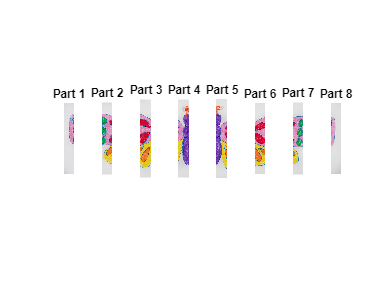

% Display the parts
    figure;
    for i = 1:numParts
        subplot(1,numParts,i), imshow(firstPart{i}), title(['Part ' num2str(i)]);
    end
end


disp('Image has been split and saved successfully.');

Image has been split and saved successfully.
